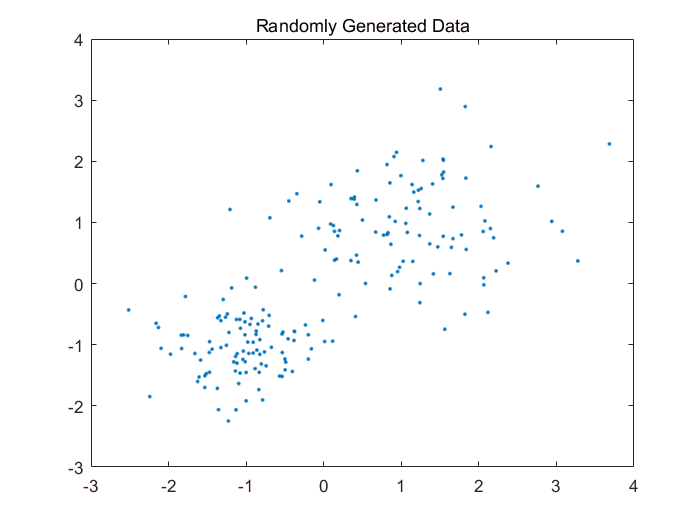

rng default; % For reproducibility
X = [randn(100,2)*0.75+ones(100,2);
    randn(100,2)*0.5-ones(100,2)];

figure;
plot(X(:,1),X(:,2),'.');
title 'Randomly Generated Data';

opts = statset('Display','final');
[idx,C] = kmeans(X,2,'Distance','cityblock',...
    'Replicates',5,'Options',opts);

Replicate 1, 3 iterations, total sum of distances = 201.533.
Replicate 2, 5 iterations, total sum of distances = 201.533.
Replicate 3, 3 iterations, total sum of distances = 201.533.
Replicate 4, 3 iterations, total sum of distances = 201.533.
Replicate 5, 2 iterations, total sum of distances = 201.533.
Best total sum of distances = 201.533


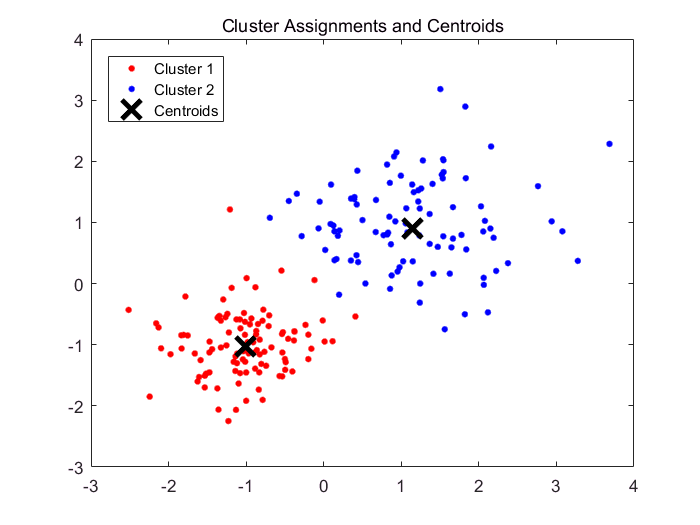

figure;
plot(X(idx==1,1),X(idx==1,2),'r.','MarkerSize',12)
hold on
plot(X(idx==2,1),X(idx==2,2),'b.','MarkerSize',12)
plot(C(:,1),C(:,2),'kx',...
     'MarkerSize',15,'LineWidth',3) 
legend('Cluster 1','Cluster 2','Centroids',...
       'Location','NW')
title 'Cluster Assignments and Centroids'
hold off